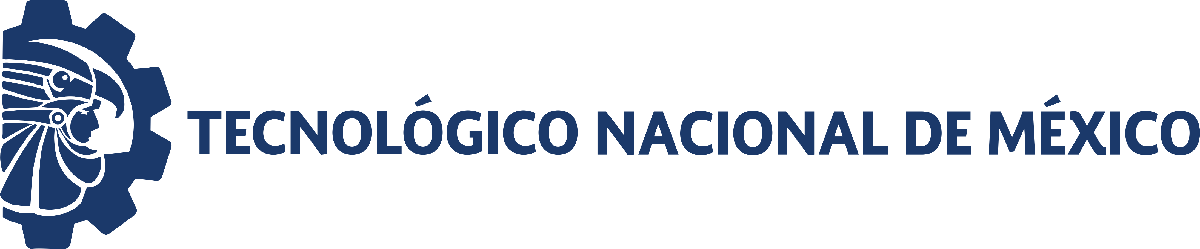                                 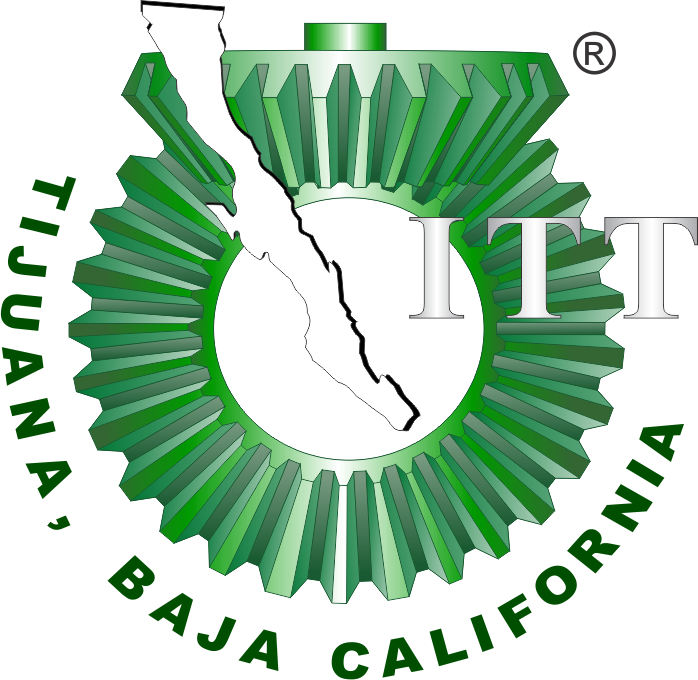

# Proyecto: Sistema Digestivo

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

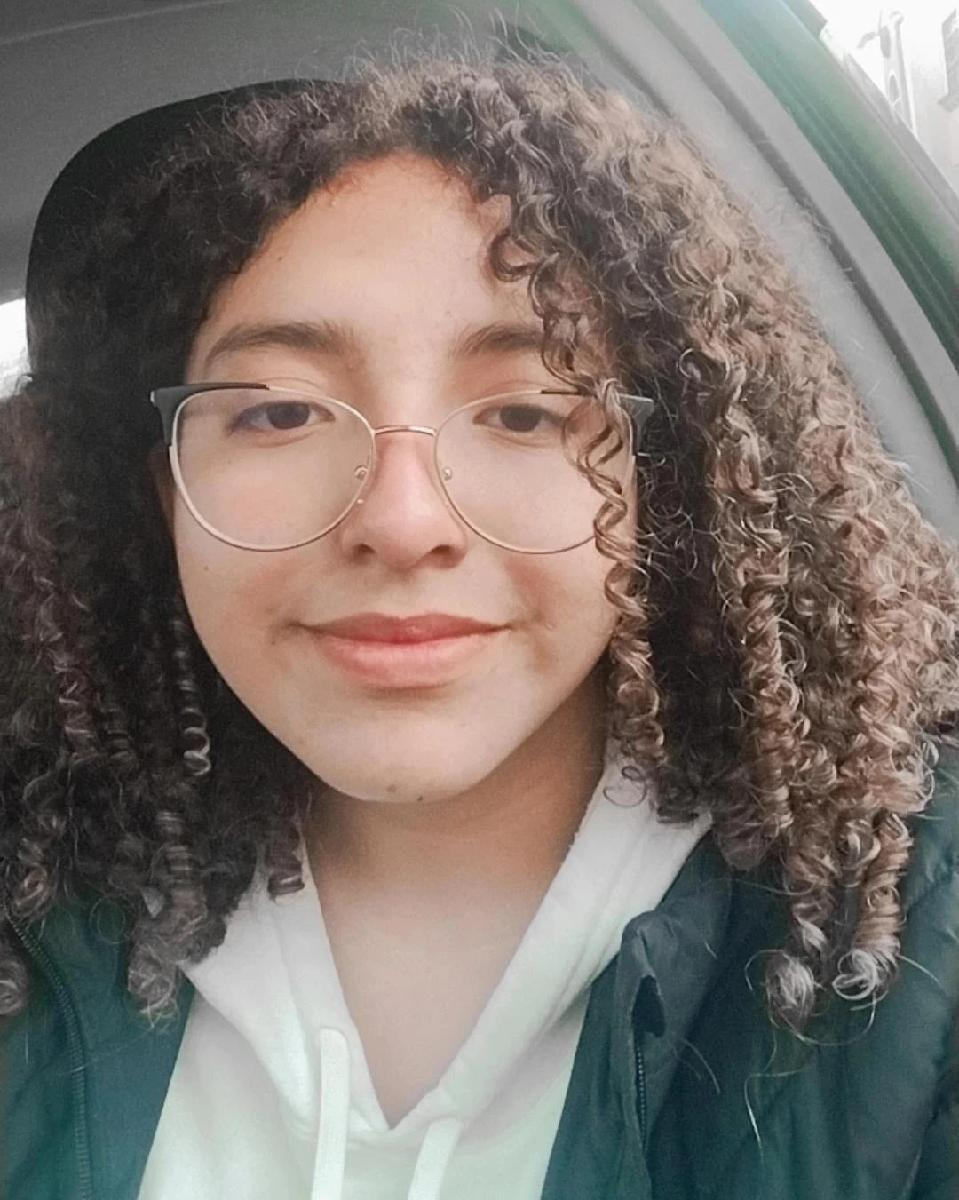 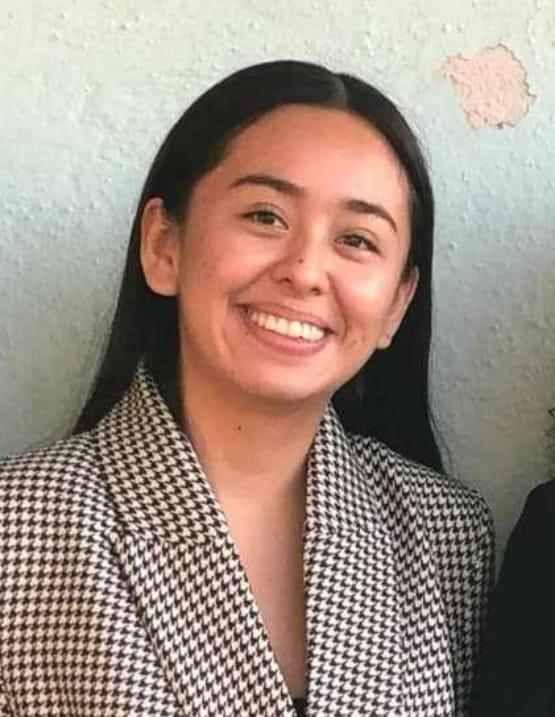 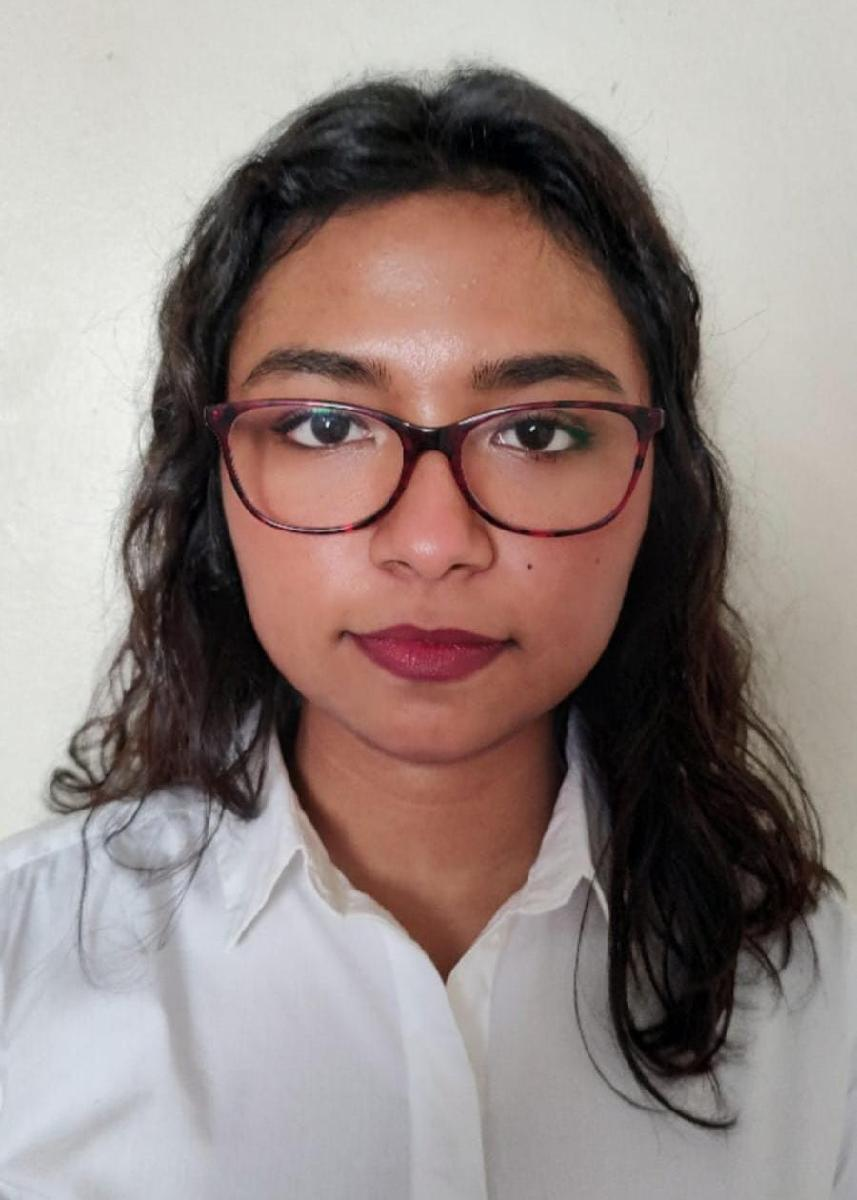

Nombre del alumno: **Angelica Xileme Cabrera Perez**

**                                Amy Stephany Lopez Garrido **

**                                Ana Carolina Santillan Cardenas**

Número de control: ** 21212144**

**|                                21212164**

**                                 21212181**

Correo institucional: **l21212144@tectijuana.edu.mx**

**                                 l21212164@tectijuana.edu.mx**

**                                 l21212181@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all');
tend = '10';
file = 'SistemaDigestivo';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';
Controlador = 'PAz';

## Parametros del controlador y rendimiento


$$\begin{array}{l}
K_p =18\ldotp 314\\
P_I =629\ldotp 14\\
K_{D\;} =4\ldotp 4200\times {10}^{-2} \\
\mathrm{Rise}\;\mathrm{Time}=0\ldotp 0129\;\mathrm{seconds}\\
\mathrm{Setting}\;\mathrm{Time}=0\ldotp 0867\;\mathrm{seconds}\\
\mathrm{Overshoot}=8\ldotp 96%\\
\mathrm{Peak}\;1\ldotp 09
\end{array}$$


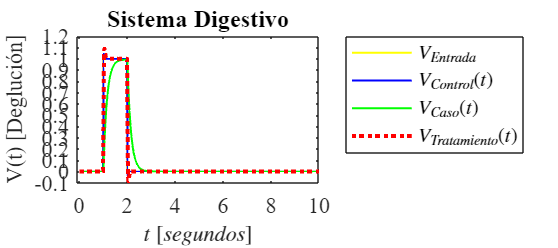

Signal = 'Sistema Digestivo';
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Pao,x1.PAx,x1.PAy,x1.PAz,Signal)

## Funciones

function plotsignals(t,Pao,PAx,PAy,PAz,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[25,1.5,18,8])
    set(gca,'Fontname','Times New Roman','Fontsize',11)
    hold on; grid off, box on

    plot(t,Pao,'Linewidth',1,'Color',[1 1 0])
    plot(t,PAx,'Linewidth',1,'Color',[0 0 1])
    plot(t,PAy,'Linewidth',1,'Color',[0 1 0])  
    plot(t,PAz,':','Linewidth',2,'Color',[1 0 0])

    % Añadir leyenda
    % Añadir leyenda
    lgd = legend('show');

    % Cambiar la posición de la leyenda
    lgd.Location = 'northeastoutside'; % Cambiar 'northeastoutside' según necesites
    L = legend('$V_{Entrada}$','$V_{ Control}(t)$','$V_{ Caso}(t)$','$V_{ Tratamiento}(t)$');
    set(L, 'Interpreter','Latex','Fontsize',10,'box','on')

    xlabel('$t$ $[segundos]$','Interpreter','Latex','FontSize',11)
    ylabel('V(t) [Deglución]','Interpreter','Latex','FontSize',11)

    if Signal == "Sistema Digestivo"
        title("Sistema Digestivo")
        xlim([-0.1,10]); xticks(0:2:10)
        ylim([-0.1,1.2]); yticks(-0.1:0.1:1.2)
    end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'Resolution',600);
    print(Signal,'-dsvg','-r600');
    print(Signal,'-depsc','-r600');
end